clear; close all; clc;
rng(0);  % For reproducibility

%% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

%% Forward chaining settings
initLen   = 365;   % first fold: 1-year training
stepLen   = 90;    % then roll by 90 days
h         = 7;      % h-step ahead prediction
N         = numel(yTrainAll);

nFolds    = floor((N - initLen) / stepLen);
fprintf('Total folds: %d\n', nFolds);

Total folds: 12



%% Model / config settings
lagListAR   = [10 90 180];   % AR(p) configurations
lagListRNN  = [10 90 180];   % RNN visible history via delays 1:p
lagListTrans  = [10 90 180]; 
nCfg        = numel(lagListAR);

numHiddenRNN  = 16;
numHiddenLSTM = 16;

%% Storage for RMSE
rmseAR_uni    = nan(nFolds, nCfg);   % folds × configs
rmseRNN_uni   = nan(nFolds, nCfg);
rmseLSTM_uni  = nan(nFolds, 1);     % LSTM not dependent on p
rmseTRANS_uni = nan(nFolds, nCfg);

%% Forward chaining over folds
for k = 1:nFolds
    
    % Training indices: from day 1 to "1 year + (k-1)*stepLen"
    idxTrain = 1 : (initLen + (k-1)*stepLen);
    
    % Validation indices: the next 'stepLen' days
    idxVal   = (initLen + (k-1)*stepLen + 1) : ...
               (initLen + k*stepLen);
    
    yTrain_raw = yTrainAll(idxTrain);
    yVal_raw   = yTrainAll(idxVal);

    % Normalization (only using training statistics)
    mu  = mean(yTrain_raw);
    sig = std(yTrain_raw);
    if sig == 0, sig = 1; end

    yTrain = (yTrain_raw - mu) / sig;
    yVal   = (yVal_raw   - mu) / sig;

    Ntr = numel(yTrain);

    %% 1. LSTM (fixed config, 1-step ahead)
    XTrainLSTM = {yTrain(1:end-h)'};  % 1×1 cell, row vector
    YTrainLSTM = {yTrain(1+h:end)'};

    inputSize      = 1;
    numHiddenUnits = numHiddenLSTM;
    outputSize     = 1;

    layers = [ ...
        sequenceInputLayer(inputSize)
        lstmLayer(numHiddenUnits, 'OutputMode','sequence')
        fullyConnectedLayer(outputSize)
        regressionLayer];

    options = trainingOptions('adam', ...
        'MaxEpochs', 60, ...
        'GradientThreshold', 1, ...
        'InitialLearnRate', 0.01, ...
        'Verbose', false, ...
        'Plots', 'none');

    netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

    % Validation prediction (no warm start here)
    XValLSTM        = {yVal(1:end-h)'};
    YValTrue_LSTMn  = yVal(1+h:end);

    YPredCell       = predict(netLSTM, XValLSTM, 'MiniBatchSize', 1);
    YValPred_LSTMn  = YPredCell{1}(:)';   % row vector

    % Align lengths
    lenPred = length(YValPred_LSTMn);
    lenTrue = length(YValTrue_LSTMn);
    if lenTrue > lenPred
        YValTrue_LSTMn = YValTrue_LSTMn(end-lenPred+1:end);
    elseif lenPred > lenTrue
        YValPred_LSTMn = YValPred_LSTMn(end-lenTrue+1:end);
    end

    % De-normalize
    YValPred_LSTM = YValPred_LSTMn * sig + mu;
    YValTrue_LSTM = YValTrue_LSTMn * sig + mu;

    YValPred_LSTM = YValPred_LSTM(:)';
    YValTrue_LSTM = YValTrue_LSTM(:)';
    
    rmseLSTM_uni(k) = sqrt(mean((YValPred_LSTM - YValTrue_LSTM).^2));

    %% 2. Loop over different visible history lengths p
    for c = 1:nCfg
        pAR  = lagListAR(c);    % AR(p)
        pRNN = lagListRNN(c);   % RNN delays 1:pRNN
        pTrans = lagListTrans(c);  % Transformer sequence lentgh

        %% AR(p) baseline via linear regression (fitlm) + warm start
        if Ntr <= pAR + 1
            warning('Fold %d, AR(%d): training length too short. Skipping.', k, pAR);
        else
            N_eff = Ntr - pAR - h + 1;

            Xtr_AR = zeros(N_eff, pAR);
            Ytr_AR = zeros(N_eff, 1);
            
            for t = 1:N_eff
                % Input: p AR lags
                Xtr_AR(t, :) = yTrain(t + pAR - 1 : -1 : t).';   % reverse slice for convenience
                
                % Target: value h steps ahead
                Ytr_AR(t) = yTrain(t + pAR - 1 + h);
            end

            mdlAR = fitlm(Xtr_AR, Ytr_AR);
            
            % Concatenate full ground truth data (Train + Val)
            y_true_all = [yTrain; yVal];

            % Initialize container for validation predictions
            YValPred_AR_norm = zeros(numel(yVal), 1);

            % Loop over each time step in the validation set
            for t = 1:numel(yVal)
            
                % Start with true history available at this validation time
                idxEnd   = Ntr + t - 1;
                idxStart = idxEnd - pAR + 1;
                histVals = y_true_all(idxStart:idxEnd);   % p AR lags
            
                % Recursively predict until step = 7
                for step = 1:h
                    x = histVals(end-pAR+1:end)';   % last p lags as a row
                    yhat = predict(mdlAR, x);
                    histVals = [histVals; yhat];    % append prediction
                end
            
                % Store ONLY the 7th-step prediction
                YValPred_AR_norm(t) = histVals(end);
            end

            YValTrue_norm = yVal(h:end);
            YValPred_AR_norm = YValPred_AR_norm(1:end-h+1);

            % Align lengths (Safety check, though lengths should match now)
            lenPred = length(YValPred_AR_norm);
            lenTrue = length(YValTrue_norm);
            if lenTrue > lenPred
                YValTrue_norm = YValTrue_norm(end-lenPred+1:end);
            elseif lenPred > lenTrue
                YValPred_AR_norm = YValPred_AR_norm(end-lenTrue+1:end);
            end

            % De-normalize
            YValPred_AR = YValPred_AR_norm * sig + mu;
            YValTrue    = YValTrue_norm * sig + mu;

            rmseAR_uni(k, c) = sqrt(mean((YValPred_AR - YValTrue).^2));
        end

        %% 2.2) RNN (layrecnet) with delays 1:pRNN + warm start, true h-step-ahead
        if Ntr <= pRNN + 2
            warning('Fold %d, RNN(p=%d): training length too short. Skipping.', k, pRNN);
        else
            % 1-step ahead training
            X_rnn = num2cell(yTrain(1:end-1)');
            T_rnn = num2cell(yTrain(2:end)');
            
            netRNN = layrecnet(1:pRNN, numHiddenRNN);
            netRNN.trainFcn = 'trainscg';
            netRNN.trainParam.showWindow = false;
            
            [Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
            netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);
            
            [~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);
        
            % Warm-started validation prediction
            nVal = numel(yVal);
            y_true_all = [yTrain; yVal];
        
            YValPred_rnn_norm = zeros(nVal - h + 1, 1);
            YValTrue_rnn_norm = yVal(h:end);
        
            for t = 1:(nVal - h + 1)
                idxEnd = Ntr + t - 1;
                idxStart = idxEnd - pRNN + 1;
                histVals = y_true_all(idxStart:idxEnd);   % last pRNN true values
            
                for step = 1:h
                    Xseq = num2cell(histVals(end-pRNN+1:end)');
                    yhat = netRNN(Xseq, Xf_rnn, Af_rnn);
                    histVals = [histVals; yhat{end}];
                end
                YValPred_rnn_norm(t) = histVals(end);
            end
        
            % De-normalize and compute RMSE
            YValPred_RNN = YValPred_rnn_norm * sig + mu;
            YValTrue_RNN = YValTrue_rnn_norm * sig + mu;
            rmseRNN_uni(k, c) = sqrt(mean((YValPred_RNN - YValTrue_RNN).^2));
        end

        %% Transformer        
        embeddingOutputSize = 16;
        maxPosition         = 180;
        numHeads            = 4;
        numKeyChannels      = 4*embeddingOutputSize;
        
        layers = [ 
            sequenceInputLayer(1, Name="input")          % 1 feature
            positionEmbeddingLayer(embeddingOutputSize,maxPosition, ...
                PositionDimension="temporal", Name="word-emb")
            additionLayer(2,Name="add")
            selfAttentionLayer(numHeads,numKeyChannels, Name="attn")
            fullyConnectedLayer(1, Name="fc")
            regressionLayer(Name="output")
        ];
        lgraph = layerGraph(layers);
        lgraph = connectLayers(lgraph,"input","add/in2");
        
        options = trainingOptions('adam', ...
            'MaxEpochs', 50, ...
            'MiniBatchSize', 32, ...
            'SequenceLength', pTrans, ...
            'Verbose', false);
        
        % Prepare univariate training sequences (from yTrain)
        XTrainSeq = num2cell(yTrain(1:end-1));
        YTrainSeq = num2cell(yTrain(2:end));
        
        netTrans_uni = trainNetwork(XTrainSeq, YTrainSeq, lgraph, options);

        y_true_all = [yTrain; yVal];
        y_all = [yTrain; zeros(numel(yVal),1)];

        for t = 1:(length(yVal)-h+1)
            histY = y_true_all(Ntr + t - pTrans : Ntr + t - 1);  % initial pTrans
            
            for step = 1:h
                Xseq = {histY(end-pTrans+1:end)'};
                yhat = predict(netTrans_uni, Xseq);
                histY = [histY; yhat{1}(end)];   % append new prediction
            end
            
            y_all(Ntr + t + h - 1) = histY(end);  % store last prediction
        end
        
        YTrans_test_norm = y_all(h:end);
        YValTrue_trans_norm = yVal(h:end);

        % Align lengths
        L = min(length(YTrans_test_norm), length(YValTrue_trans_norm));
        YTrans_test_norm = YTrans_test_norm(end-L+1:end);
        YValTrue_trans_norm = YValTrue_trans_norm(end-L+1:end);
        
        % Denormalize
        YTrans_test = YTrans_test_norm * sig + mu;
        YValTrue_trans = YValTrue_trans_norm * sig + mu;
        
        % Store RMSE
        rmseTRANS_uni(k,c) = sqrt(mean((YTrans_test - YValTrue_trans).^2));

    end

    %% Fold summary print
    fprintf("Fold %2d | LSTM RMSE = %.4f\n", k, rmseLSTM_uni(k));
    for c = 1:nCfg
        fprintf("   Config p=%3d | AR RMSE = %.4f | RNN RMSE = %.4f | TRANS RMSE = %.4f\n", ...
            lagListAR(c), rmseAR_uni(k,c), rmseRNN_uni(k,c), rmseTRANS_uni(k,c));

    end
end

Fold  1 | LSTM RMSE = 2.2388


   Config p= 10 | AR RMSE = 2.3782 | RNN RMSE = 4.1408 | TRANS RMSE = 2.2585
   Config p= 90 | AR RMSE = 8.1771 | RNN RMSE = 7.8928 | TRANS RMSE = 4.9133
   Config p=180 | AR RMSE = 11.0079 | RNN RMSE = 4.8514 | TRANS RMSE = 6.9711


Fold  2 | LSTM RMSE = 3.1353


   Config p= 10 | AR RMSE = 3.1182 | RNN RMSE = 5.1253 | TRANS RMSE = 3.2338
   Config p= 90 | AR RMSE = 16.3894 | RNN RMSE = 10.6611 | TRANS RMSE = 7.8920
   Config p=180 | AR RMSE = 15.7064 | RNN RMSE = 5.6299 | TRANS RMSE = 11.9080


%% Overall RMSE summary (mean over folds)
meanAR   = mean(rmseAR_uni, 1, 'omitnan');
meanRNN  = mean(rmseRNN_uni, 1, 'omitnan');
meanLSTM = mean(rmseLSTM_uni, 1, 'omitnan');
meanTRANS = mean(rmseTRANS_uni, 1, 'omitnan');

fprintf("\n=== Univariate forward-chaining (year+90d blocks) RMSE (mean over folds) ===\n");


=== Univariate forward-chaining (year+90d blocks) RMSE (mean over folds) ===


for c = 1:nCfg
    fprintf("AR(%3d) : %.4f\n", lagListAR(c),  meanAR(c));
end

AR( 10) : 2.9080
AR( 90) : 9.5888
AR(180) : 12.5918


for c = 1:nCfg
    fprintf("RNN(1:%3d) : %.4f\n", lagListRNN(c),  meanRNN(c));
end

RNN(1: 10) : 4.4325
RNN(1: 90) : 6.5366
RNN(1:180) : 8.7509


for c = 1:nCfg
    fprintf("Transformer(p=%3d) : %.4f\n", lagListTrans(c), meanTRANS(c));
end

Transformer(p= 10) : 7.4615
Transformer(p= 90) : 7.6053
Transformer(p=180) : 7.4739


fprintf("LSTM (fixed config) : %.4f\n", meanLSTM);

LSTM (fixed config) : 2.8803


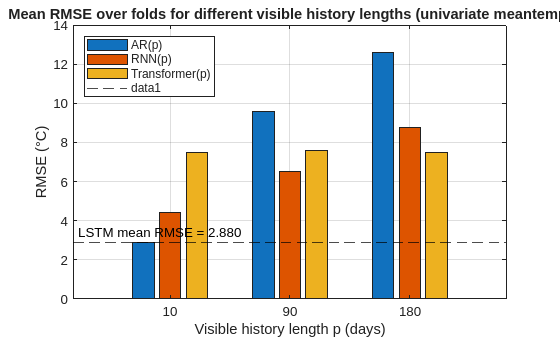


%% mean RMSE vs visible history length (bar chart)
figure;

xCats = categorical(string(lagListAR));
xCats = reordercats(xCats, string(lagListAR));

barData = [meanAR(:) meanRNN(:) meanTRANS(:)];
bar(xCats, barData);
ylabel('RMSE (°C)');
xlabel('Visible history length p (days)');
title('Mean RMSE over folds for different visible history lengths (univariate meantemp)');
legend({'AR(p)','RNN(p)','Transformer(p)'}, 'Location','northwest');
grid on;
hold on;

yline(meanLSTM, '--k', sprintf('LSTM mean RMSE = %.3f', meanLSTM), ...
    'LabelHorizontalAlignment','left');

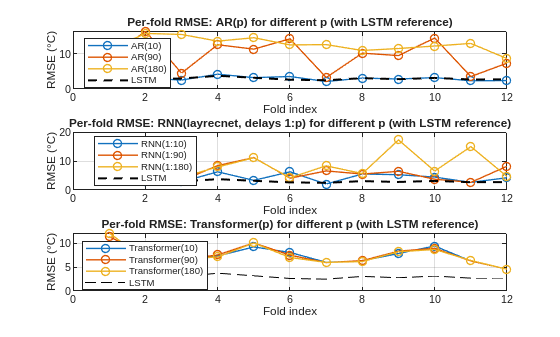


%% per-fold RMSE curves
figure;
tFolds = 1:nFolds;

% AR curves
subplot(3,1,1);
plot(tFolds, rmseAR_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, 'k--', 'LineWidth', 1.5);
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: AR(p) for different p (with LSTM reference)');
legendStrings = arrayfun(@(p)sprintf('AR(%d)',p), lagListAR, 'UniformOutput', false);
legend([legendStrings {'LSTM'}], 'Location','best');

% RNN curves
subplot(3,1,2);
plot(tFolds, rmseRNN_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, 'k--', 'LineWidth', 1.5);
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: RNN(layrecnet, delays 1:p) for different p (with LSTM reference)');
legendStringsR = arrayfun(@(p)sprintf('RNN(1:%d)',p), lagListRNN, 'UniformOutput', false);
legend([legendStringsR {'LSTM'}], 'Location','best');

% Transformer curves
subplot(3,1,3);
plot(tFolds, rmseTRANS_uni, '-o', 'LineWidth', 1); hold on;
plot(tFolds, rmseLSTM_uni, 'k--');  
grid on;
xlabel('Fold index');
ylabel('RMSE (°C)');
title('Per-fold RMSE: Transformer(p) for different p (with LSTM reference)');
legendStrings = arrayfun(@(p)sprintf('Transformer(%d)',p), lagListAR, 'UniformOutput', false);
legend([legendStrings {'LSTM'}], 'Location','best');

%% Final comparison on TEST set (AR vs RNN vs LSTM with warm start for AR & RNN)
clear; close all; clc;
rng(0);  % For reproducibility

% Load data
trainData = readtable('DailyDelhiClimateTrain.csv');
testData  = readtable('DailyDelhiClimateTest.csv');

yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

% 1. Normalization based on TRAIN only 
mu  = mean(yTrainAll);
sig = std(yTrainAll);
if sig == 0, sig = 1; end

yTrain = (yTrainAll - mu) / sig;
yTest  = (yTestAll  - mu) / sig;

%% 2. AR(90) baseline on test set (recursive, warm start)

noLagsAR = 10;
h = 7;
Ntr = numel(yTrain);

if Ntr <= noLagsAR + 1
    error("Training series too short for AR(%d).", noLagsAR);
end

% build AR training set on train data
N_eff = Ntr - noLagsAR - h + 1;

Xtr_AR = zeros(N_eff, noLagsAR);
Ytr_AR = zeros(N_eff, 1);

for t = 1:N_eff
    Xtr_AR(t, :) = yTrain(t + noLagsAR - 1 : -1 : t).';
    Ytr_AR(t)    = yTrain(t + noLagsAR - 1 + h);    % target shifted by +7
end

mdlAR = fitlm(Xtr_AR, Ytr_AR);

% one step
y_true_all = [yTrain; yTest]; 
Y_AR_test_norm = zeros(numel(yTest) - h, 1);

for t = 1:(numel(yTest) - h)
    % last p values available at this test time
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - noLagsAR + 1;

    lastVals = y_true_all(idxStart : idxEnd);
    lastVals = lastVals(:)';     % row vector

    Y_AR_test_norm(t) = predict(mdlAR, lastVals);
end

Y_AR_test_true = yTest(1+h:end);   % shift ground truth


%% 3. RNN (layrecnet, delays 1:90) on test set with warm start

% 1-step ahead training on train data
X_rnn = num2cell(yTrain(1:end-1)');   % 1-step inputs
T_rnn = num2cell(yTrain(2:end)');     % 1-step targets

pRNN         = 10;
numHiddenRNN = 16;
netRNN = layrecnet(1:pRNN, numHiddenRNN);
netRNN.trainFcn = 'trainscg';
netRNN.trainParam.showWindow = false;

[Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

[~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);

% Direct 7-step-ahead RNN test predictions
y_true_all = [yTrain; yTest];
nTest = numel(yTest);

Y_RNN_test_norm = zeros(nTest - h, 1);
YTrue_rnn_test  = yTest(h+1:end);  % ground truth shifted by h

for t = 1:(nTest - h)
    % Last pRNN true values before prediction
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pRNN + 1;
    histVals = y_true_all(idxStart:idxEnd);   % last pRNN true values
    
    % Recursively predict h steps ahead
    for step = 1:h
        Xseq = num2cell(histVals(end-pRNN+1:end)');
        yhat = netRNN(Xseq, Xf_rnn, Af_rnn);
        histVals = [histVals; yhat{end}];
    end
    
    Y_RNN_test_norm(t) = histVals(end);   % store h-step prediction
end

%% 4. LSTM on test set (no explicit window, 1-step ahead)

XTrainLSTM = {yTrain(1:end-h)'};
YTrainLSTM = {yTrain(1+h:end)'};

numHiddenLSTM = 16;

layers = [ ...
    sequenceInputLayer(1)
    lstmLayer(numHiddenLSTM,'OutputMode','sequence')
    fullyConnectedLayer(1)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 60, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'Verbose', false, ...
    'Plots', 'none');

netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

XTestLSTM        = {yTest(1:end-h)'};
YTrue_LSTM_testn = yTest(1+h:end);

Y_test_cell      = predict(netLSTM, XTestLSTM, 'MiniBatchSize', 1);
Y_LSTM_test_norm = Y_test_cell{1}(:)';

%% Transformer

pTrans = 10;
embeddingOutputSize = 16;
maxPosition         = 180;
numHeads            = 4;
numKeyChannels      = 4*embeddingOutputSize;

layers = [ 
    sequenceInputLayer(1, Name="input")          % 1 feature
    positionEmbeddingLayer(embeddingOutputSize,maxPosition, ...
        PositionDimension="temporal", Name="word-emb")
    additionLayer(2,Name="add")
    selfAttentionLayer(numHeads,numKeyChannels, Name="attn")
    fullyConnectedLayer(1, Name="fc")
    regressionLayer(Name="output")
];
lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph,"input","add/in2");

options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'SequenceLength', pTrans, ...
    'Verbose', false);

XTrainSeq = num2cell(yTrain(1:end-1));
YTrainSeq = num2cell(yTrain(2:end));

netTrans_uni = trainNetwork(XTrainSeq, YTrainSeq, lgraph, options);

y_true_all = [yTrain; yTest];
y_all = [yTrain; zeros(numel(yTest),1)];

for t = 1:(length(yTest)-h+1)
    histY = y_true_all(Ntr + t - pTrans : Ntr + t - 1);  % initial pTrans
    
    for step = 1:h
        Xseq = {histY(end-pTrans+1:end)'};
        yhat = predict(netTrans_uni, Xseq);
        histY = [histY; yhat{1}(end)];   % append new prediction
    end
    
    y_all(Ntr + t + h - 1) = histY(end);  % store last prediction
end


YTrans_test_norm = y_all(Ntr+h:end);

%% RMSE

lenAR   = length(Y_AR_test_norm);
lenRNN  = length(Y_RNN_test_norm);
lenLSTM = length(Y_LSTM_test_norm);
lenT    = length(YTrue_rnn_test);
lenTrans = length(YTrans_test_norm);

L = min([lenAR, lenRNN, lenLSTM, lenTrans, lenT]);

Y_AR_test_norm   = Y_AR_test_norm(end-L+1:end);
Y_RNN_test_norm  = Y_RNN_test_norm(end-L+1:end);
Y_LSTM_test_norm = Y_LSTM_test_norm(end-L+1:end);
YTrans_test_norm  = YTrans_test_norm(end-L+1:end);
Y_true_test_norm = YTrue_rnn_test(end-L+1:end);

Y_AR_test   = Y_AR_test_norm   * sig + mu;
Y_RNN_test  = Y_RNN_test_norm  * sig + mu;
Y_LSTM_test = Y_LSTM_test_norm * sig + mu;
Y_LSTM_test = Y_LSTM_test(:);
Y_TRANS_test  = YTrans_test_norm  * sig + mu;
Y_true_test = Y_true_test_norm * sig + mu;

% RMSE
rmseAR   = sqrt(mean((Y_AR_test   - Y_true_test).^2));
rmseRNN  = sqrt(mean((Y_RNN_test  - Y_true_test).^2));
rmseLSTM = sqrt(mean((Y_LSTM_test - Y_true_test).^2));
rmseTRANS   = sqrt(mean((Y_TRANS_test  - Y_true_test).^2));

fprintf('Test RMSE | AR(%d)=%.4f | RNN(1:%d)=%.4f | LSTM=%.4f | TRANS(p=%d)=%.4f\n', ...
        noLagsAR, rmseAR, pRNN, rmseRNN, rmseLSTM, pTrans, rmseTRANS);

Test RMSE | AR(10)=4.0222 | RNN(1:10)=6.9071 | LSTM=3.5032 | TRANS(p=10)=3.5472


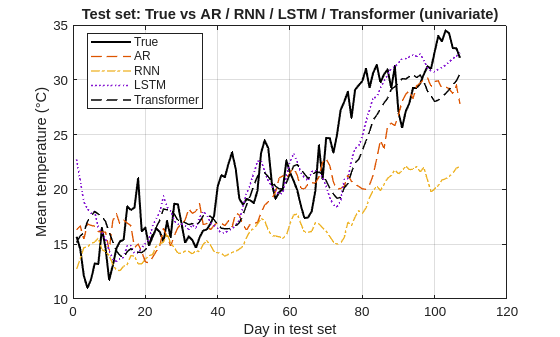

%% Plot

figure;
plot(Y_true_test, 'k', 'LineWidth', 1.5); hold on;
plot(Y_AR_test,   '--', 'LineWidth', 1);
plot(Y_RNN_test,  '-.', 'LineWidth', 1);
plot(Y_LSTM_test, ':',  'LineWidth', 1.2);
plot(Y_TRANS_test, '--k', 'LineWidth', 1.1);

legend('True','AR','RNN','LSTM','Transformer','Location','best');
xlabel('Day in test set');
ylabel('Mean temperature (°C)');
title('Test set: True vs AR / RNN / LSTM / Transformer (univariate)');
grid on;

%% Multivariate
clearvars -except trainData testData h pRNN numHiddenRNN numHiddenLSTM
rng(0);

varsTrain = [trainData.meantemp, trainData.humidity, ...
             trainData.wind_speed, trainData.meanpressure];
varsTest  = [testData.meantemp,  testData.humidity, ...
             testData.wind_speed, testData.meanpressure];

% Prediction target: next-day mean temperature
yTrainAll = trainData.meantemp;
yTestAll  = testData.meantemp;

[numTrain, numVars] = size(varsTrain);

%% Normalization (per variable, using TRAIN only)
muX  = mean(varsTrain, 1);
sigX = std(varsTrain, 0, 1); 
sigX(sigX == 0) = 1;

XTrain = (varsTrain - muX) ./ sigX;      % numTrain × numVars
XTest  = (varsTest  - muX) ./ sigX;

muy  = mean(yTrainAll);
sigy = std(yTrainAll); 
if sigy == 0, sigy = 1; end

yTrain = (yTrainAll - muy) / sigy;
yTest  = (yTestAll  - muy) / sigy;

%% Multivariate AR baseline ( VAR-like, with lags on all variables )
pAR = 90;                     % visible history length
Ntr = numTrain;               % number of train observations

if Ntr <= pAR + 1
    error("Training series too short for AR(%d).", pAR);
end

Xtr_AR = zeros(Ntr - pAR, pAR * numVars);
Ytr_AR = yTrain(pAR+1:end);      % predict y(t) from past X's

for lag = 1:pAR
    % slice rows pAR-lag+1 : Ntr-lag, take all variables
    block = XTrain(pAR - lag + 1 : end - lag, :);   % (Ntr - pAR) × numVars
    colIdx = (lag-1)*numVars + (1:numVars);         % columns for this lag
    Xtr_AR(:, colIdx) = block;
end

mdlAR = fitlm(Xtr_AR, Ytr_AR);

% Recursive multi-step forecast on test set (normalized)
y_all = [yTrain; zeros(numel(yTest),1)];    % concat train + placeholder
X_all = [XTrain; XTest];                    % full normalized inputs


for t = 1:(length(yTest)-h+1)
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pAR + 1;
    window   = X_all(idxStart:idxEnd, :);
    
    % recursively predict h steps
    histY = y_all(idxEnd - pAR + 1 : idxEnd);
    for step = 1:h
        xRow = flipud(window);      % reverse in time
        xRow = reshape(xRow.', 1, []); % 1 × (pAR*numVars)
        yhat = predict(mdlAR, xRow);
        histY = [histY; yhat];
        % append last row to window for next recursion
        if step < h
            window = [window(2:end,:); XTest(t+step-1,:)]; 
        end
    end
    
    y_all(Ntr + t + h - 1) = histY(end);
end

Y_AR_test_norm = y_all(Ntr+h:end);
Y_AR_test      = Y_AR_test_norm * sigy + muy;

%% Multivariate RNN (layrecnet) — inputs are 4-dim vectors

X_rnn = cell(1, Ntr-1);
T_rnn = cell(1, Ntr-1);

for t = 1:Ntr-1
    X_rnn{t} = XTrain(t, :)';
    T_rnn{t} = yTrain(t+1); 
end

pRNN         = 10;          % delays 1:pRNN
numHiddenRNN = 16;

netRNN = layrecnet(1:pRNN, numHiddenRNN);
netRNN.trainFcn = 'trainscg';
netRNN.trainParam.showWindow = false;

[Xs_rnn, Xi_rnn, Ai_rnn, Ts_rnn] = preparets(netRNN, X_rnn, T_rnn);
netRNN = train(netRNN, Xs_rnn, Ts_rnn, Xi_rnn, Ai_rnn);

[~, Xf_rnn, Af_rnn] = netRNN(Xs_rnn, Xi_rnn, Ai_rnn);

% Recursive h-step prediction on test
y_all = [yTrain; zeros(length(yTest),1)];
X_all = [XTrain; XTest];

for t = 1:(length(yTest)-h+1)
    idxEnd   = Ntr + t - 1;
    idxStart = idxEnd - pRNN + 1;
    
    histX = X_all(idxStart:idxEnd, :);
    histY = y_all(idxEnd - pRNN + 1 : idxEnd);
    
    for step = 1:h
        Xseq = cell(1,pRNN);
        for i = 1:pRNN
            Xseq{i} = histX(i,:)';
        end
        yhat = netRNN(Xseq, Xf_rnn, Af_rnn);
        histY = [histY; yhat{end}];
    end
    
    y_all(Ntr + t + h - 1) = histY(end);
end

Y_RNN_test_norm = y_all(Ntr+h:end);
Y_RNN_test = Y_RNN_test_norm * sigy + muy;
Y_true_rnn = yTest(h:end) * sigy + muy;

%% Multivariate LSTM

XTrainLSTM = {XTrain(1:end-h,:)'};
YTrainLSTM = {yTrain(1+h:end)'};

inputSize      = numVars;
numHiddenLSTM  = 16;
outputSize     = 1;

layers = [ ...
    sequenceInputLayer(inputSize)
    lstmLayer(numHiddenLSTM,'OutputMode','sequence')
    fullyConnectedLayer(outputSize)
    regressionLayer];

options = trainingOptions('adam', ...
    'MaxEpochs', 60, ...
    'GradientThreshold', 1, ...
    'InitialLearnRate', 0.01, ...
    'Verbose', false, ...
    'Plots', 'none');

netLSTM = trainNetwork(XTrainLSTM, YTrainLSTM, layers, options);

% Test sequence
XTestLSTM        = {XTest(1:end-h,:)'};
YTrue_LSTM_norm  = yTest(1+h:end);

YPredCell        = predict(netLSTM, XTestLSTM, 'MiniBatchSize', 1);
Y_LSTM_test_norm = YPredCell{1}(:)';

Y_LSTM_test = Y_LSTM_test_norm * sigy + muy;
Y_true_LSTM = YTrue_LSTM_norm * sigy + muy;


%% Multivariate Transformer

pTrans = 10;
embeddingOutputSize = 16;
maxPosition = 180;
numHeads = 4;
numKeyChannels = 4*embeddingOutputSize;

% Define Transformer layers
layers = [ 
    sequenceInputLayer(numVars, Name="input")
    fullyConnectedLayer(embeddingOutputSize, Name="input_proj")
    positionEmbeddingLayer(embeddingOutputSize,maxPosition,...
        PositionDimension="temporal", Name="word-emb")
    additionLayer(2,Name="add")
    selfAttentionLayer(numHeads,numKeyChannels, Name="attn")
    fullyConnectedLayer(numVars, Name="fc")
    regressionLayer(Name="output")
];
lgraph = layerGraph(layers);
lgraph = connectLayers(lgraph,"input_proj","add/in2");

options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 32, ...
    'SequenceLength', pTrans, ...
    'Verbose', false);

% Prepare multivariate training sequences
Ntr = size(XTrain,1);
numSequences = Ntr - pTrans - h + 1;

XTrainCell = cell(numSequences,1);
YTrainCell = cell(numSequences,1);

for t = 1:numSequences
    XTrainCell{t} = XTrain(t:t+pTrans-1, :)';
    YTrainCell{t} = XTrain(t + h:t+pTrans + h-1, :)';
end

% Train Transformer
netTrans_multi = trainNetwork(XTrainCell, YTrainCell, lgraph, options);


% Initialize full sequence
nTest = size(XTest,1);
X_all = [XTrain; XTest];
Y_all = [XTrain(:, 1); zeros(nTest, 1)];  % to store predictions

% Autoregressive prediction
for t = 1:(nTest - h + 1)
    histX = X_all(Ntr + t - pTrans : Ntr + t - 1, :)';
    
    for step = 1:h
        Xseq = {histX(:, end-pTrans+1:end)};  
        Ypred = predict(netTrans_multi, Xseq);
        Ynext = Ypred{1}(:, end);   % numVars x 1 vector
        
        % Append new prediction
        histX = [histX, Ynext];   % keep last pTrans updated in next loop
    end
    
    % Store last prediction
    Y_all(Ntr + t + h - 1) = histXVec(1, end)';
end

% Extract predictions for test set
YTransPred_norm = Y_all(Ntr + h:end, :);


% Align lengths
L = min(length(YTransPred_norm), nTest);
YTransPred_norm = YTransPred_norm(end-L+1:end);

% Denormalize
YTransPred = YTransPred_norm * sigy + muy;

%% Align lengths & compute RMSE

% AR has length = length(yTest), RNN/LSTM length = length(yTest)-1
lenAR   = length(Y_AR_test);
lenRNN  = length(Y_RNN_test);
lenLSTM = length(Y_LSTM_test);
lenT    = length(Y_true_LSTM);
lenTrans = length(YTransPred);
L = min([lenAR, lenRNN, lenLSTM, lenT, lenTrans]);

Y_AR_test   = Y_AR_test(end-L+1:end);
Y_RNN_test  = Y_RNN_test(end-L+1:end);
Y_LSTM_test = Y_LSTM_test(end-L+1:end);
Y_LSTM_test = Y_LSTM_test(:);
Y_true_test = Y_true_LSTM(end-L+1:end);
Y_Trans_test = YTransPred(end-L+1:end);

rmseAR   = sqrt(mean((Y_AR_test   - Y_true_test).^2));
rmseRNN  = sqrt(mean((Y_RNN_test  - Y_true_test).^2));
rmseLSTM = sqrt(mean((Y_LSTM_test - Y_true_test).^2));
rmseTRANS = sqrt(mean((Y_Trans_test - Y_true_test).^2));

fprintf('Multivariate test RMSE | AR(p=%d)=%.4f | RNN(1:%d)=%.4f | LSTM=%.4f | TRANS(1:%d)=%.4f\n', ...
        pAR, rmseAR, pRNN, rmseRNN, rmseLSTM, pTrans, rmseTRANS);

Multivariate test RMSE | AR(p=90)=1.8021 | RNN(1:10)=4.6014 | LSTM=3.1001 | TRANS(1:10)=10.9688


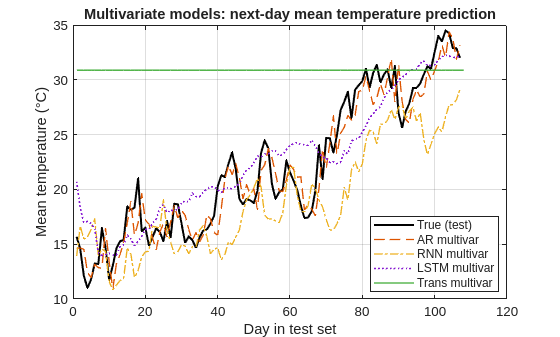

%% Plot: test truth vs three models (multivariate inputs)
figure;
plot(Y_true_test, 'k', 'LineWidth', 1.5); hold on;
plot(Y_AR_test,   '--', 'LineWidth', 1);
plot(Y_RNN_test,  '-.', 'LineWidth', 1);
plot(Y_LSTM_test, ':',  'LineWidth', 1.2);
plot(YTransPred, '-', 'LineWidth', 1);
legend('True (test)','AR multivar','RNN multivar','LSTM multivar', 'Trans multivar','Location','best');
xlabel('Day in test set');
ylabel('Mean temperature (°C)');
title('Multivariate models: next-day mean temperature prediction');
grid on;